# Levitador de aire

**Trabajo para el curso sistemas lineales, 2025-1**

**© **[**Universidad EAFIT**](https://www.eafit.edu.co)**, Medellín, Antioquia, Colombia**

- **Santiago López **- [slopezc12@eafit.edu.co](mailto:slopezc12@eafit.edu.co)

- **Ricardo Gandica **- [jrgandicav@eafit.edu.co](mailto:jrgandicav@eafit.edu.co)

## ***Introducción***

## Métodos

## Resultados

### Sistema en Simulink

%Tiempo máximo
T = 10;

% Create time vector (e.g., 0 to 10 seconds in 0.1 increments)
%time = 0:0.1:T;
time = linspace(0, T, length(y1))

time =          0    0.0315    0.0631    0.0946    0.1262    0.1577    0.1893    0.2208    0.2524    0.2839    0.3155    0.3470    0.3785    0.4101    0.4416    0.4732    0.5047    0.5363    0.5678    0.5994    0.6309    0.6625    0.6940    0.7256    0.7571    0.7886    0.8202    0.8517    0.8833    0.9148    0.9464    0.9779    1.0095    1.0410    1.0726    1.1041    1.1356    1.1672    1.1987    1.2303    1.2618    1.2934    1.3249    1.3565    1.3880    1.4196    1.4511    1.4826    1.5142    1.5457



% Create corresponding data vector (example: sine wave)
cs = 5;
data = ones(size(time)) * cs;
% Create timeseries object
%u = timeseries(data, time)
u = [time', data']

u =          0    5.0000
    0.0315    5.0000
    0.0631    5.0000
    0.0946    5.0000
    0.1262    5.0000
    0.1577    5.0000
    0.1893    5.0000
    0.2208    5.0000
    0.2524    5.0000
    0.2839    5.0000


%Parámetros
g = 9.81;
m = 3.84 * 10^-3;

A = 5.7 * 10^-3;
Cd = 0.74;
rho = 1.23;

tao1 = 0.14;
kf = 7.78;
alfa = (1/2) * rho * A * Cd;
ci = zeros(1, 3);

kp = 0.5;
ki = 0.1;
kd = 0.01;

sim = ('Levitador_aire_parametrizado')

sim = 'Levitador_aire_parametrizado'

y1 = y.signals.values;
y2 = dy.signals.values;
y3 = va.signals.values;

y.signals.values

ans =          0
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0002
   -0.0007


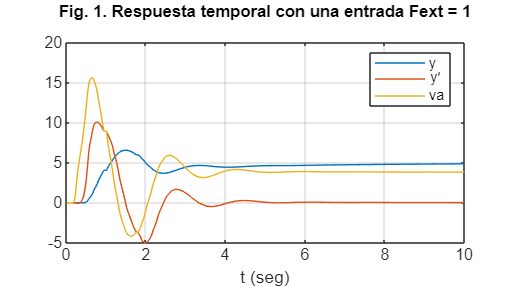


%figure('Units','normalized','Position',[0 0 0.3 0.3])

plot(time,y1,time,y2,time,y3)
legend('y','y\prime', 'va'), xlabel('t (seg)'), grid
title({'Fig. 1. Respuesta temporal con una entrada Fext = 1';''},'FontSize',10,'FontWeight','bold')

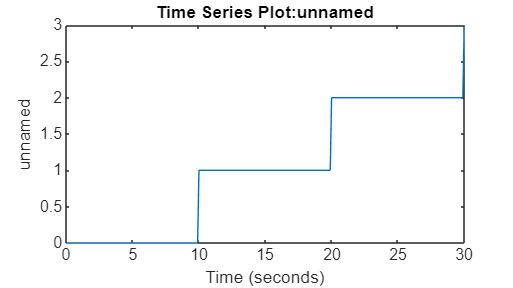

function u = ladder(T, dt, step_duration, step_size, initial_value)
    % Time vector
    time = 0:dt:T;

    % Number of steps
    num_steps = floor(T / step_duration);

    % Step values
    ladder_values = initial_value + step_size * (0:num_steps);

    % Repeat each value for the duration of a step
    samples_per_step = round(step_duration / dt);
    data = repelem(ladder_values, samples_per_step);

    % Adjust data length to match time vector
    if length(data) > length(time)
        data = data(1:length(time));
    elseif length(data) < length(time)
        data = [data, repmat(data(end), 1, length(time) - length(data))];
    end

    % Create timeseries object
    u = timeseries(data', time');
end
T = 30;
dt = 0.1;
step_duration = 10;
step_size = 1;
initial_value = 0;

u = ladder(T, dt, step_duration, step_size, initial_value);

plot(u);  % Visualize the signal

### Verificación del modelo

## Discusión

## **Referencias**